# MPU6050 Sensor Integration with Raspberry Pi Zero 2W

In this live script I interfaced with MPU6050 through RPi zero 2w and matlab

### Connect your rpi with matlab

 % Use raspi() function and specify the ip address and password to connect
 % with you rpi

### Create MPU object

mpu = mpu6050(r2);          

### Real time plotting of sensor data through I2C

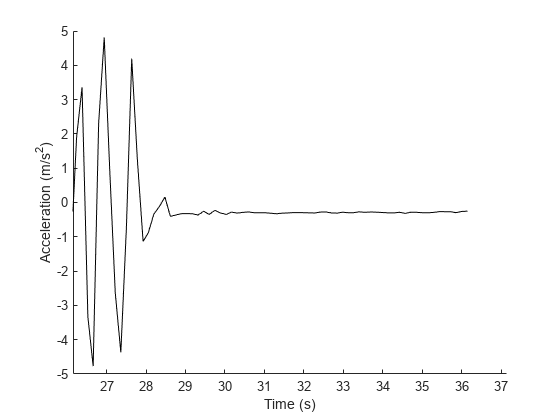

% Set up figure for real-time plotting
figure;
h = animatedline;

% Set the plot axis labels
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

% Set up time vector for x-axis
time = 0;
tic; % Start the timer

% Main loop for real-time data acquisition
while ishandle(h.Parent)
    % Read accelerometer data
    accelData = readAcceleration(mpu);

    % Update time vector
    time = [time, toc];

    % Add data point to the plot
    addpoints(h, time(end), accelData(1));

    % Update plot limits for better visualization
    xlim([time(end)-10, time(end)+1]);

    % Pause for a short interval
    pause(0.1);
end


% Clean up
clear mpu;